% Generate sample data
covmtx = blkdiag(toeplitz([1 .6 .6]), toeplitz([1 .6 .6]));  % two orthogonal latent sources, 3 measures each
x = mvnrnd(ones(1, 6), covmtx, 500);

% Image correlation matrix
create_figure('corr'); 
imagesc(corr(x)); colorbar; set(gca, 'YDir', 'Reverse'); axis tight;
canlab_redblue_symmetric_colormap;

% 
create_figure('corr2'); 
plot_correlation_matrix(x);


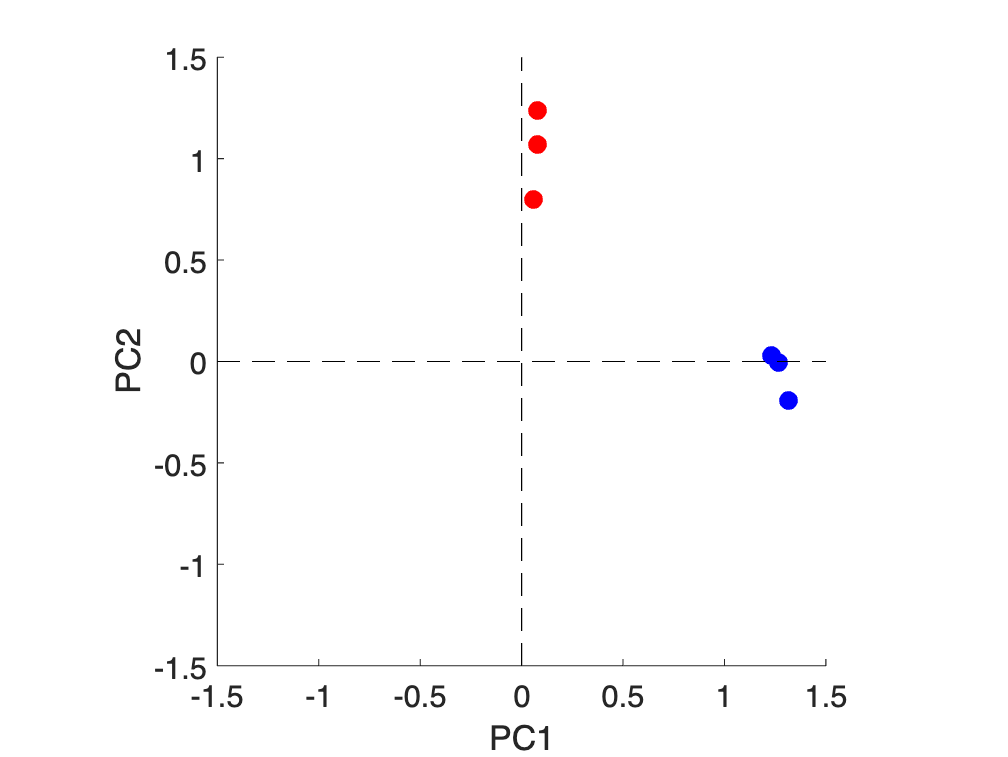

n = 100;

covmtx = blkdiag(toeplitz([1 .6 .6]), toeplitz([1 .6 .6]));  % two orthogonal latent sources, 3 measures each
x = mvnrnd(ones(1, 6), covmtx, n);

[coeff, score, latent, tsquared, explained] = pca(x);

create_figure('coeff'); 
% plot(coeff(:, 1), coeff(:, 2), 'ko'); 
wh1 = 1:3; wh2 = 4:6;  % two clusters

plot(coeff(wh1, 1) * latent(1), coeff(wh1, 2) * latent(2), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
plot(coeff(wh2, 1) * latent(1), coeff(wh2, 2) * latent(2), 'bo', 'MarkerFaceColor', 'b', 'MarkerSize', 8);

xlabel('PC1'); ylabel('PC2');

set(gca, 'XLim', [-1.5 1.5], 'YLim', [-1.5 1.5]);

hh = plot_horizontal_line(0); set(hh, 'LineStyle', '--');
hh = plot_vertical_line(0); set(hh, 'LineStyle', '--');
axis tight
axis equal